code for generating Figure 4

Adapted from pipeline3.mlx

Uses the data file dat3_litParams_7-1-2020.mat (without the initcellulose = 960mg series)

Filters

%filter out rows which didn't grow (by increasing its biomass by a fixed amount)
filter1 = true; %growth by 2x
filter1 = false;
filter1b = true; %growth by 10x
filter1b = false;
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
end

%2x
growers = zeros(nrows,1);
for i = 1:nrows
    if dat3.biomass{i}(1) < max(dat3.biomass{i})/2
        growers(i) = true;
    end
end
nongrowers = ~growers;
dat3.did_grow = growers;
if filter1
    dat3 = dat3(logical(growers),:);
end

%10x
growers = zeros(nrows,1);
for i = 1:nrows
    if dat3.biomass{i}(1) < max(dat3.biomass{i})/10
        growers(i) = true;
    end
end
nongrowers = ~growers;
dat3.did_grow10x = growers;
if filter1b
    dat3 = dat3(logical(growers),:);
end

%filter out rows which didn't achieve complete cellulose conversion
filter2 = true;
%filter2 = false;
filter2_threshold = .010; %fraction of initcel   
filter2_alphathreshold = -2.5; %minimum log10 of series to check for this filter 
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
end
incomplete_conversion = zeros(nrows,1);
for i = 1:nrows
    if dat3.cellulose_amt{i}(end) > initcellulose * filter2_threshold
        if (log10(dat3.alpha(i)) >= filter2_alphathreshold) 
        incomplete_conversion(i) = true;
        end
    end
end
dat3.incomplete_conversion = incomplete_conversion;
if filter2
    dat3 = dat3(~incomplete_conversion,:);
end

%keep the longest-running row for each cellulose/alpha pair
filter3 = true;
if ~ismember('runtime',dat3.Properties.VariableNames)
    dat3.runtime = cellfun(@(x) max(x),dat3.t);
end
filter3_redundant_rows = 0;
alphas = unique(dat3.alpha);
initcels = unique(dat3.initcel);
[nrows,~] = size(dat3);
if filter3
    t = table();
    for ia = 1:length(alphas)
        a = alphas(ia);
        for ic = 1:length(initcels)
            c = initcels(ic);
            idx = dat3.alpha == a & dat3.initcel == c;
            if sum(idx) > 0
                rows = dat3(idx,:);
                row = rows(rows.runtime == max(rows.runtime),:);
                row = row(1,:);
                t = vertcat(t,row);
            end
        end
    end
    [trows,~] = size(t);
    filter3_redundant_rows = nrows - trows;
    dat3 = t;
end

## **Find the alpha that produces the best yield**

dat3_partial = dat3(mod(log10(dat3.alpha),1) == .25,:);
dat3_partial = dat3;

initcelamts = unique(dat3_partial.initcel);

%REMOVE THE INITCEL 960 SERIES
initcelamts = initcelamts(initcelamts < .0265);

glcpercellulose = 218.2;
g_avicel = (initcelamts) * (180.156 - 17) * glcpercellulose / 1000;
ic = initcelamts(1);
ydat = dat3_partial(dat3_partial.initcel == ic,:);



%plot yield / a for each cel amount
f = figure();
subplot(2,2,1);
hold on;

colors = parula(1+length(initcelamts));
besta_yield = zeros(length(initcelamts),1);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
   plot(log10(d.alpha),d.yield,'color',colors(i,:),'linewidth',2);
    besta_yield(i) = mode(log10(d.alpha(d.biomass_max==max(d.biomass_max))));
    %scatter(besta_yield(i),max(d.yield),50,colors(i,:),'+','HandleVisibility','off');
end
hold off;
ylabel('Yield (g Biomass / g Cellulose)');
xlabel('Log10(\alpha)');
text(-.3,1,'A','FontSize',fontsize,'Units',"normalized");




## %Find the alpha that produces the best growth rate

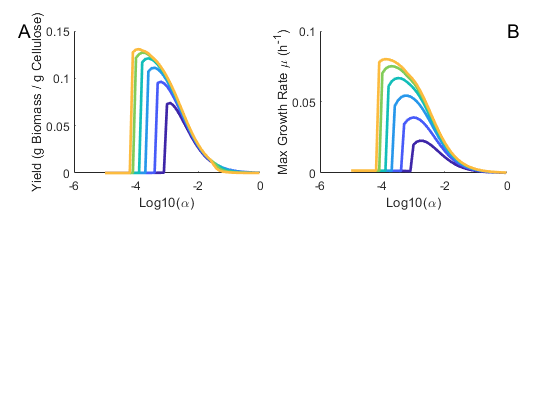

dat3_partial = dat3(mod(log10(dat3.alpha),1) == 0,:);
dat3_partial = dat3;

initcelamts = unique(dat3_partial.initcel);
%REMOVE THE INITCEL 960 SERIES
initcelamts = initcelamts(initcelamts < .0265);

glcpercellulose = 218.2;
g_avicel = (initcelamts/1000) * (180.156 - 17) * glcpercellulose;

ic = initcelamts(1);
ydat = dat3_partial(dat3_partial.initcel == ic,:);




%f = figure();
subplot(2,2,2);
hold on;
besta_rate2 = zeros(size(initcelamts));
maxrate = 0;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    r = cellfun(@(x) max(x),deltas);
    plot(log10(d.alpha),r,'color',colors(i,:),'linewidth',2);
    maxrate = max([maxrate;r]);
    besta_rate2(i) = mode(log10(d.alpha(r==max(r))));
end
hold off;
ylabel('Max Growth Rate \mu (h^-^1)');
xlabel('Log10(\alpha)');

text(1,1,'B','FontSize',fontsize,'Units',"normalized");

## Compare best alpha for yield and rate

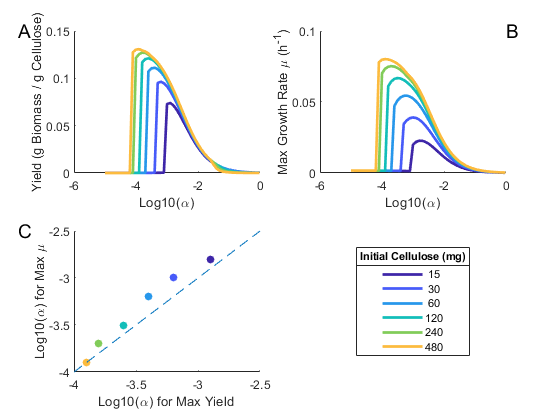

scatterlabel = num2str(1000 * g_avicel);


colors = parula(1+length(scatterlabel));
colors = colors(1:length(scatterlabel),:);

subplot(2,2,3);

scatter(besta_yield,besta_rate2,[],colors,'filled');
hold on;
lin = line([-4,-2.5],[-4,-2.5]);
set(lin,'LineStyle','--')
textdelta = .03;
%text(besta_yield + textdelta,besta_rate2 + textdelta, scatterlabel);
%text(besta_yield + textdelta,besta_rate + textdelta, {'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'});
hold off;
xlabel('Log10(\alpha) for Max Yield');
ylabel('Log10(\alpha) for Max \mu');
%xlim([-10 -5]);
%ylim([-10 -5]);
text(-.3,1,'C','FontSize',fontsize,'Units',"normalized");


%add the legend in subplot 4
subplot(2,2,4);

%copying one of the other figs just to get the data series in here...
hold on;
besta_rate2 = zeros(size(initcelamts));
maxrate = 0;
colors = parula(1+length(initcelamts));
%colors = parula(1+nrows);
for i = 1:length(initcelamts)
    amt = initcelamts(i);
    d = dat3(dat3.initcel == amt,:);
    [nrows,~] = size(d);
    deltas = cell(nrows,1);
    for j = 1:nrows
        deltas{j} = d.biomass_delta{j} ./ d.biomass{j}(1:end-1); 
    end
    r = cellfun(@(x) max(x),deltas);
    plot(0,0,'color',colors(i,:),'linewidth',2);
    maxrate = max([maxrate;r]);
    besta_rate2(i) = mode(log10(d.alpha(r==max(r))));
end
hold off;
axis off;

leg = legend(num2str(g_avicel*1000),'location','best');
title(leg,'Initial Cellulose (mg)')

if overwritefiles
    saveas(f,'.\figs\figure4.fig');
    saveas(f,'.\figs\figure4.png');
    saveas(f,'.\figs\figure4.eps');%for LaTeX
end